# Figure 4E

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';


load([dataDir filesep 'A033_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 40×7 cell array
    {'siCtrl 6hr DMSO'              }    {[1 2]}    {[ 2]}    {[1 2 3 4 5 6]}    {[39]}    {[0 0 0]}    {[0 10]}
    {'siCtrl 6hr TAK 500nM'         }    {[1 2]}    {[ 3]}    {[1 2 3 4 5 6]}    {[39]}    {[0 0 0]}    {[0 10]}
    {'siCtrl 6hr RO 10uM'           }    {[1 2]}    {[ 4]}    {[1 2 3 4 5 6]}    {[39]}    {[0 0 0]}    {[0 10]}
    {'siCtrl 6hr RO 10uM/ TAK'      }    {[1 2]}    {[ 5]}    {[1 2 3 4 5 6]}    {[39]}    {[0 0 0]}    {[0 10]}
    {'siCtrl 6hr 2i 1uM'            }    {[1 2]}    {[ 6]}    {[1 2 3 4 5 6]}    {[39]}    {[0 0 0]}    {[0 10]}
    {'siCtrl 6hr 2i 1uM/TAK'        }    {[1 2]}    {[ 7]}    {[1 2 3 4 5 6]}    {[39]}    {[0 0 0]}    {[0 10]}
    {'siCtrl 6hr 2i 1uM/ RO 10uM'   }    {[1 2]}    {[ 8]}    {[1 2 3 4 5 6]}    {[39]}    {[0 0 0]}    {[0 10]}
    {'siCtrl 6hr ATRi/TAK'          }    {[1 2]}    {[ 9]}    {[1 2 3 4 5 6]}    {[39]}    {[0 0 0]}    {[0 10]}
    {'siCtrl 6hr ATRi/TAK/RO 10uM'  }    {[1 2]}    {[10]}    {[1 2


framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = (frameDrugAdded - S(i).POI)/framesPerHr;
end

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
    cdkLowGate = false(length(dat.POI(:,1)),1);
     cdkGateAll = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
      
       
        if dat.POI(n,1) > 1 * framesPerHr
            crlGate(n) = dat.crlNuc(n,dat.POI(n,1) - 1 * framesPerHr) >  100;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;
     
   S(i).crlGate = crlGate;
     

end

**Gate cells**

xthresh = 4.7e5; %x value of peak
xrange = linspace(0,9e5,1000); %row vector of 1000 points between x and y (all the data)
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange); %probility density plot of values from all xdata to xrange - max x of first peak
    xi_trunc = xi(xi<xthresh); %xi_trunc = all xdata <x thresh (peak of first peak)
    f_trunc = f(xi<xthresh); % f_trunc = probability density estimate for all xdata <x tresh
    [~, maxi] = max(f_trunc); %maxi = index of peak
    N_peak = xi_trunc(maxi); %peak is max of (all xdata<x thresh) which is at index maxi
    S(i).DNA_peak = N_peak;
end

4E


colors =  [.5 .5 .5;.1 .4 1;.6 .9 .2;.9 .4 .2;.8 .4 .4];


conds=[1 21 2  22 7] ;
POI_align = 1;
ally = [];
groups = [];
timeGate = [0 20];

 perc99=[];
    perc=[];
perc1=[];
     for i = 1:length(conds)
       
            ind= ~isnan(S(conds(i)).POI(:,1)) & S(conds(i)).POI_time(:,1)>= 3& S(conds(i)).POI_time(:,1)<=5;
      sum(ind)
    
        ydata = [];

         ydata(:, 1) = (((S(conds(i)).iRFP1(ind)-150)));
        ydata(:, 2) = 2*(S(conds(i)).dna(ind)/S(conds(i)).DNA_peak);
        ydata(:, 3) = (((S(conds(i)).YFP1(ind)-5)));
        ydata(:,4) = (ydata(:,1)./ydata(:,3));
    

           yvals = ydata(:,4);

perc99(i)=prctile(yvals,99);  
perc1(i)=prctile(yvals,1); 

 ind = ydata(:,4) > perc1(i) & ydata(:,4) <perc99(i);

 yvals = ydata(ind,4);
  
              ally = [ally; yvals];
            groups = [groups; repmat(i,size(yvals))];
            length(yvals);

  

      end

ans = 4327

ans = 3927

ans = 3684

ans = 3679

ans = 510

 

cols = repmat({colors(1,:),colors(2,:),colors(3,:),colors(4,:),colors(5,:)}',1,1);
groupcol = repmat([colors([1 2 3 4 5],:)],1,1);
 figure ('units','inches','position',[0 0 6 6])

h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1,'histOri','left','widthDiv',[2 1]);

set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.05);
ylabel([ 'pMCM2(Ser27) / MCM2'])


median_test1 =mediantest(ally(groups==1),ally(groups==2))

median_test1 = 7.9091e-38

median_test2 =mediantest(ally(groups==3),ally(groups==4)) 

median_test2 = 2.2955e-14

median_test3 =mediantest(ally(groups==1),ally(groups==3))

median_test3 = 7.1527e-58

median_test4 =mediantest(ally(groups==2),ally(groups==4))

median_test4 = 4.6325e-106

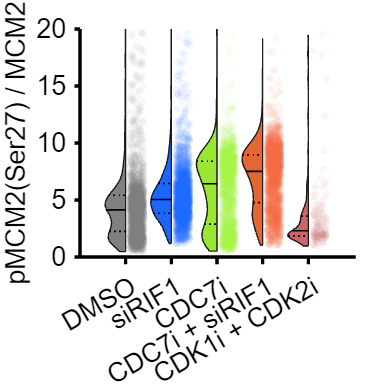



xticklabels({'DMSO','siRIF1','CDC7i','CDC7i + siRIF1','CDK1i + CDK2i'})
 ylim([0 20])
 set(gca,'fontsize',16,'linewidth',2)

hold off

% print_pdf(['fig_4e.pdf'])